clear
% Initial Condition And Assumption
P2old=10; P2new=20;
%W=(3:1:30);
L=1;
error=P2new-P2old;
% Constraints
V=1150;
Q=10;
Cv=1;
% Cost Function
H=((Q/Cv)^2+P2old)/9.8;

% Jacobi
i=1;
ai=[];
bi=[];
ci=[];
di=[];
ei=[];
ai(1)=H;
bi(1)=L;
ci(1)=P2new;
di(1)=1;
ei(1)=1;
aj=[];
bj=[];
cj=[];
dj=[];
ej=[];
aj(1)=H;
bj(1)=L;
cj(1)=P2new;
dj(1)=1;
ej(1)=1;
j=2;
im=1;
am=[];
cm=[];
em=[];
am(1)=H;
cm(1)=P2new;
em(1)=error;
for W=(10:1:15)
    %W=W(j)
    %H
    %W=10
    am(im)=H;
    cm(im)=P2new;
    em(im)=error;
    H=((Q/Cv)^2+P2old)/9.8;
    L=V/(H*W);
    k=solv_k(L,W)
    %k=0.6;
    i=2;

    error=1;
    while error>1*10^-5
        P2old=H*9.81-(Q/Cv)^2;
        L=V/(H*W);
        H=Hopt(L,k);
        P2new=H*9.81-(Q/Cv)^2;
        P2new=abs(P2new)
        H=((Q/Cv)^2+P2new)/9.8;
        ai(i)=H;
        bi(i)=L;
        ci(i)=P2new;
        di(i)=i;
        aj(j)=H;
        bj(j)=L;
        cj(j)=P2new;
        dj(j)=j;
        %fprintf('\n%3.0f %3.0f %3.0f %d', H, L, W, i)
        error=abs(cj(j-1)-cj(j));
        ei(i)=error;
        ej(j)=error;
        ik=i-1;
%         if i>100
%             break
%         end
        i=i+1;
        j=1+j;

    end
    im=im+1;
end

I = 6

V = 1.1668e+03

k = 0.6000

$$P2new = 11.720031450793568322211472833588$$

$$P2new = 13.127746842519295978919969225366$$

$$P2new = 14.271043573902409528588987451794$$

$$P2new = 15.193775777490948912450940306073$$

$$P2new = 15.93470861390296169827544378603$$

$$P2new = 16.527220084631643263979384869833$$

$$P2new = 16.99948113649315543670775273632$$

$$P2new = 17.374905619825284218130558786535$$

$$P2new = 17.672723642166019291589174251085$$

$$P2new = 17.908583816583117242946100129619$$

$$P2new = 18.095128782860284325067291243868$$

$$P2new = 18.242515189677774561183928407595$$

$$P2new = 18.358866567404507613439830398561$$

$$P2new = 18.450657844662815069903048659954$$

$$P2new = 18.523035908530653227017085097345$$

$$P2new = 18.580083268492497065894812535982$$

$$P2new = 18.62503274319387980443991575422$$

$$P2new = 18.660440933574241246652474012584$$

$$P2new = 18.688327574698599586848735922384$$

$$P2new = 18.710286973299732548224450875854$$

$$P2new = 18.727576811640817080897787967275$$

$$P2new = 18.741188722744518053122537422411$$

$$P2new = 18.751904260139205821073020474567$$

$$P2new = 18.760339211393196235564964003698$$

$$P2new = 18.766978637605476398404019921869$$

$$P2new = 18.772204551695016616806488488758$$

$$P2new = 18.776317764593097130141260094299$$

$$P2new = 18.779555117476851410723647887985$$

$$P2new = 18.782103067870427395246075887829$$

$$P2new = 18.784108396973835898429705562267$$

$$P2new = 18.785686645656014486449098054447$$

$$P2new = 18.786928759349904051417554921879$$

$$P2new = 18.787906321151153012621152114261$$

$$P2new = 18.788675672470042921795736221184$$

$$P2new = 18.789281157344565065602448982781$$

$$P2new = 18.789757676553432238778522415529$$

$$P2new = 18.790132698219452285020853737329$$

$$P2new = 18.790427840471875617125634684501$$

$$P2new = 18.790660117196431264244129630883$$

$$P2new = 18.790842918559756727142463269361$$

$$P2new = 18.790986782754754061568977128705$$

$$P2new = 18.791100003408248602867692723237$$

$$P2new = 18.791189107637382441015600268773$$

$$P2new = 18.79125923229587905831367756515$$

$$P2new = 18.791314420089241357323774246327$$

$$P2new = 18.79135785262287306245718403198$$

$$P2new = 18.791392033814053796575391374395$$

$$P2new = 18.791418934238866462392491020502$$

$$P2new = 18.791440104734111334356785925152$$

$$P2new = 18.791456765802423094156913325944$$

$$P2new = 18.791469877974245414065851911205$$

$$P2new = 18.791480197182712195084440145487$$

$$P2new = 18.791488318343617399475467870953$$

I = 7

V = 1.1594e+03

k = 0.7000

$$P2new = 20.005254276829618037303844594564$$

$$P2new = 20.820436936362951068109193215357$$

$$P2new = 21.425349347390468139676064378879$$

$$P2new = 21.872409861898111855287825579737$$

$$P2new = 22.201818553827648204520885825482$$

$$P2new = 22.444000262933729858379504140185$$

$$P2new = 22.621762532952552260440581078296$$

$$P2new = 22.752084582448826578325111852477$$

$$P2new = 22.847543150417947679286011741567$$

$$P2new = 22.917419879574536195945715162573$$

$$P2new = 22.968546335806359512509091317776$$

$$P2new = 23.005940957865399552584103231182$$

$$P2new = 23.033285025999633192668041407141$$

$$P2new = 23.053276142410550359942881003355$$

$$P2new = 23.067889581556683465889892106685$$

$$P2new = 23.078570904195815012704655666013$$

$$P2new = 23.086377583790336042429077122875$$

$$P2new = 23.092082966969613183624992495373$$

$$P2new = 23.096252491880226198047314316965$$

$$P2new = 23.09929951759114961092746315699$$

$$P2new = 23.101526192125294318265864746406$$

$$P2new = 23.103153354319739705581468033328$$

$$P2new = 23.104342404501048357027964622427$$

$$P2new = 23.105211296983423181155770594685$$

$$P2new = 23.105846232106126726216314109228$$

$$P2new = 23.106310203071797921081210866175$$

$$P2new = 23.106649243039557899938595809148$$

$$P2new = 23.106896990949374305982438795246$$

$$P2new = 23.107078028378943898557314797353$$

$$P2new = 23.107210318136390757267192916165$$

$$P2new = 23.107306986346696665456935146406$$

$$P2new = 23.107377624746623438007902490496$$

$$P2new = 23.107429242348230022072859944502$$

$$P2new = 23.107466960867775405358782890915$$

$$P2new = 23.107494522906897469812404514312$$

$$P2new = 23.107514663301285764487405854725$$

$$P2new = 23.107529380479112612946156081049$$

$$P2new = 23.107540134752217574779569665698$$

$$P2new = 23.107547993214144875157538067184$$

I = 8

V = 1.1535e+03

k = 0.8000

$$P2new = 23.732999258042962460906066258148$$

$$P2new = 24.07834787001076131383061348218$$

$$P2new = 24.31633761564389406213110887671$$

$$P2new = 24.480050304870878768710621570362$$

$$P2new = 24.592529552855620360008203031686$$

$$P2new = 24.669743470765733936714101797651$$

$$P2new = 24.722717979950359018257405653776$$

$$P2new = 24.759047990614366067477609271338$$

$$P2new = 24.783956378958925440807537363385$$

$$P2new = 24.801030741577219231696138947176$$

$$P2new = 24.812733485217031517849855087721$$

$$P2new = 24.820753824098896711799393436991$$

$$P2new = 24.826250138804542902385769732741$$

$$P2new = 24.830016591699342687513893941267$$

$$P2new = 24.832597551300055812424118156304$$

$$P2new = 24.834366118052868391362299560258$$

$$P2new = 24.835577987786044659099715142717$$

$$P2new = 24.836408386120705585899300858116$$

$$P2new = 24.836977388774831079924518232719$$

$$P2new = 24.837367277125530414692300951291$$

$$P2new = 24.837634433139445124232269512865$$

$$P2new = 24.837817491167389924743815977587$$

$$P2new = 24.83794292422443789970361421123$$

$$P2new = 24.838028872036498320295028778821$$

$$P2new = 24.838087764180280334086010137548$$

$$P2new = 24.838128117541028000537392798997$$

$$P2new = 24.838155767973252899686368289625$$

$$P2new = 24.838174714257510846929661567037$$

$$P2new = 24.838187696392227455693119763059$$

$$P2new = 24.838196591846506344694461757924$$

I = 9

V = 1.1497e+03

k = 0.9000

$$P2new = 25.057297783112372268956848122409$$

$$P2new = 25.116907656017935938553738535121$$

$$P2new = 25.155628596489881204709417876094$$

$$P2new = 25.180772886948595632330035637216$$

$$P2new = 25.197097606442906227005195700119$$

$$P2new = 25.207694912960101583079482631087$$

$$P2new = 25.214573647356972579649545158466$$

$$P2new = 25.219038403551443167165015867022$$

$$P2new = 25.221936224081215776249841235199$$

$$P2new = 25.223816991876978948915645753644$$

$$P2new = 25.225037645255624954705275932625$$

$$P2new = 25.22582986434970723601206253008$$

$$P2new = 25.226344021060320968080130084353$$

$$P2new = 25.226677711627197282006385341434$$

$$P2new = 25.226894278085759177806019220055$$

$$P2new = 25.227034830305655209242031680128$$

$$P2new = 25.227126048975874190932778691876$$

$$P2new = 25.227185250031159620045256364119$$

$$P2new = 25.227223671587657081384102974895$$

$$P2new = 25.227248607216659475788181057679$$

$$P2new = 25.227264790461866616319831352063$$

$$P2new = 25.227275293400917914169763333338$$

$$P2new = 25.227282109816170802209517803085$$

I = 10

V = 1.1473e+03

k = 1

$$P2new = 25.183856356603851817229419441036$$

$$P2new = 25.077882720400710040230075008794$$

$$P2new = 25.01222815148344851617785076692$$

$$P2new = 24.971530791134870528227712307257$$

$$P2new = 24.946295243807136477382309936745$$

$$P2new = 24.93064398519547845307733449151$$

$$P2new = 24.920935719265582164851524749979$$

$$P2new = 24.914913331560050525409169811966$$

$$P2new = 24.911177242215988630433943213799$$

$$P2new = 24.908859425282413125565537606792$$

$$P2new = 24.907421457079187996452995556586$$

$$P2new = 24.906529334426178992580743311235$$

$$P2new = 24.905975853019532472587513978259$$

$$P2new = 24.905632466311357505978229509722$$

$$P2new = 24.90541942435053773172547935502$$

$$P2new = 24.905287249879413426801261023408$$

$$P2new = 24.905205246739145726364122903961$$

$$P2new = 24.905154370654763425347386712646$$

$$P2new = 24.905122806289838048091803962363$$

$$P2new = 24.905103223230258754274725397611$$

$$P2new = 24.905091073570820982758840235381$$

$$P2new = 24.905083535717065443799624591303$$

I = 10

V = 1.1979e+03

k = 1

$$P2new = 30.371936294930253685696801893802$$

$$P2new = 33.678001488020492376604690823223$$

$$P2new = 35.673211370227548541232281097507$$

$$P2new = 36.859184364910713981886021169448$$

$$P2new = 37.557885893911526318862164384492$$

$$P2new = 37.967378482905765730630693136523$$

$$P2new = 38.206644082688416717964050820426$$

$$P2new = 38.346198999929488136466476441499$$

$$P2new = 38.427512374748694537972621017633$$

$$P2new = 38.474862159388343469355381038405$$

$$P2new = 38.502424889316130079554449084602$$

$$P2new = 38.518466135873822796073561771125$$

$$P2new = 38.527800883827266725290716584504$$

$$P2new = 38.53323260125948433384330963798$$

$$P2new = 38.536393090670270143714766550747$$

$$P2new = 38.538232004523976872850368876682$$

$$P2new = 38.539301952196604237256136012697$$

$$P2new = 38.539924482166929855942183912678$$

$$P2new = 38.540286688463748580541834747653$$

$$P2new = 38.54049743020660486110712185499$$

$$P2new = 38.540620045449717177539411312437$$

$$P2new = 38.540691386248371181213053065226$$

$$P2new = 38.540732894194243594217050456284$$

$$P2new = 38.54075704459731621554291599459$$

$$P2new = 38.540771095927788221397855939457$$

$$P2new = 38.540779271355211734275197137082$$

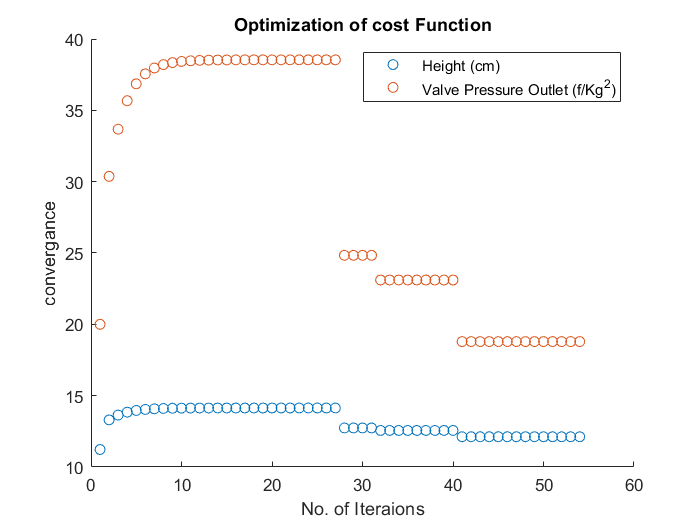

%% Plotting Variables
figure(1);
scatter(di,ai)
hold on
scatter(di,ci)
title('Plot of the Out Pressure Optimization')
xlabel('No. of Iteraions')
ylabel('convergance')
title('Optimization of cost Function')
legend('Height (cm)','Valve Pressure Outlet (f/Kg^2)')

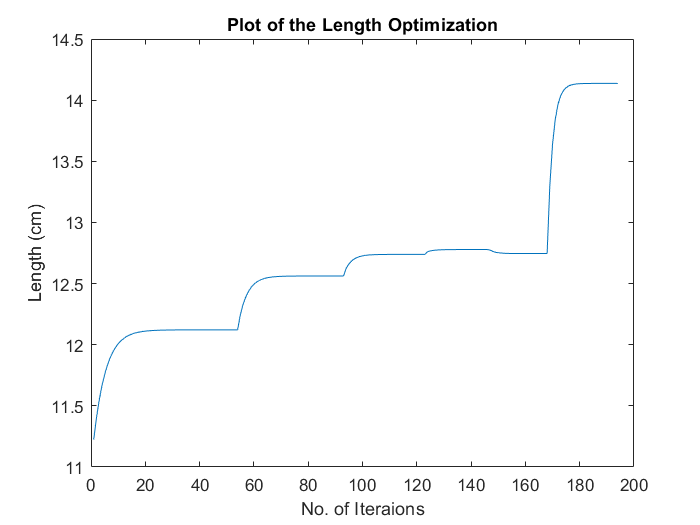

figure(2);
plot(dj,aj)
xlabel('No. of Iteraions')
ylabel('Length (cm)')
title('Plot of the Length Optimization')

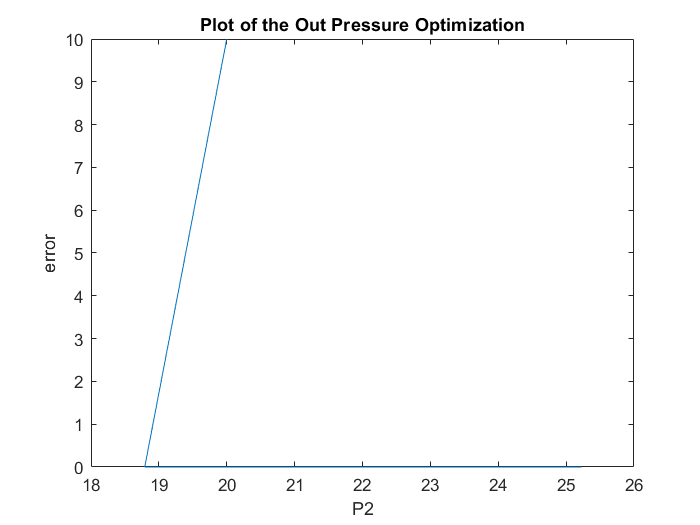

figure(3);
plot(cm,em)
title('Plot of the Out Pressure Optimization')
xlabel('P2')
ylabel('error')

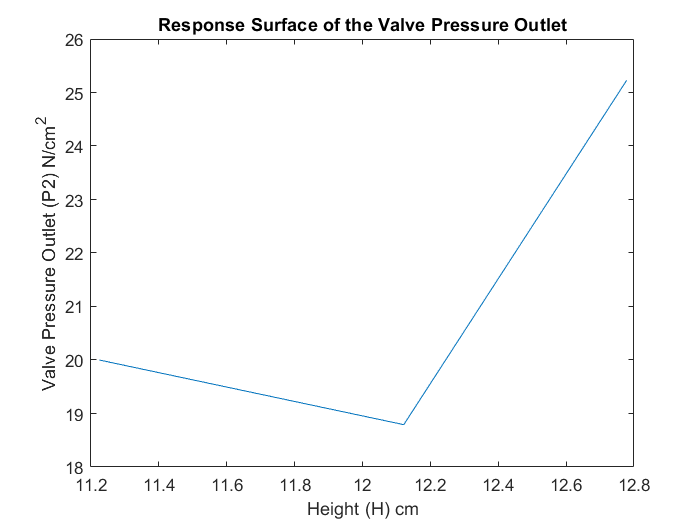

figure(4);
plot(am,cm)
title('Response Surface of the Valve Pressure Outlet')
xlabel('Height (H) cm')
ylabel('Valve Pressure Outlet (P2) N/cm^2')

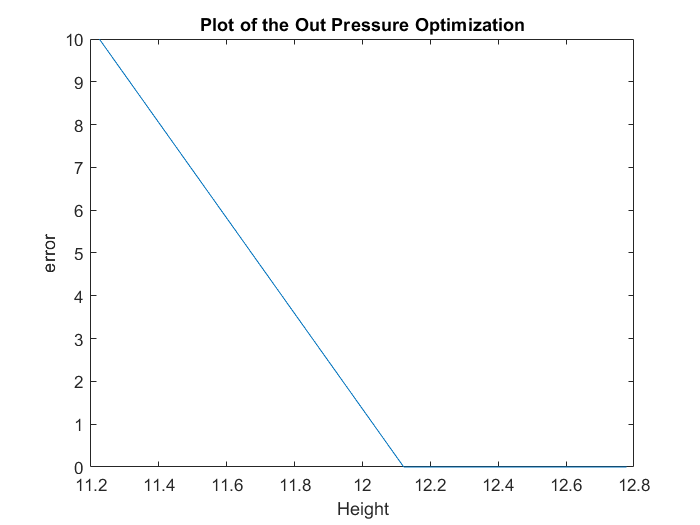

figure(5);
plot(am,em)
title('Plot of the Out Pressure Optimization')
xlabel('Height')
ylabel('error')


% Export to Excel
R1(1:j-1,1)=aj;
R2(1:j-1,1)=bj;
R3(1:j-1,1)=cj;
R4(1:j-1,1)=dj;
R5(1:j-1,1)=ej;
columnname={'Iteration','Height','Lenght','Outlet_Pressure','Pressure_Error'};
R=table(R4,R1,R2,R3,R5,'VariableNames',columnname);
%delete optimization.xlsx
writetable(R,'optimization.xlsx');
type 'optimization.xlsx';

P¹ŒRNÀÈ–[Content_Types].xmlµ’ËNÃ0EÅòÅNY „’tQ`	H”0Î$±â—ìiIÿÇ)Bé‚EW~Ü;sfFSm'£ÉBTÎÖtÃJJÀJ×*Û×ôcÿ\ÜÓmSíO"IVk: úÎ£ÀˆÈœ›”Î#0=CÏ½£èß–å—Î"X,pÎA›ê:qÐHž¦ô½`èHÉn1Î¬š
ïµ’“Î¶ýC)Î–"³'ÊÇ›d |•0+—ç¸×4‡ ZøW%®ë”„ÖÉƒI!,ú¢ÍòÉŒP6×FÞDÀaRV>iþåÂøéÜÈ®ÇÇ“†¸Æ^”ë‘çÞòýRãYŒ<›+N`Úwi¡×ñÛðSÏß|P¹ŒRÑé½¤_rels/.relsA‚0D¯Òü½]c(lŒ	[ƒ¨åShÓVÅÛÛ¥.'3ó&S5‹ÙC4äl‹:E½qZÀµ;oÐÔÕg™r"ŽÆG–+.
SòGÎ£ÑÊXG—‚•)Ë ¹—j’ù®,÷<|2`Íd“€eæO
Óh*2X÷òøÏ
ƒQx"u·èÒÅ¯°¶Ú~¼®øê`ýP¹ŒRG>´‹Ì#xl/_rels/workbook.xml.rels­‘ÁŠÂ0†_%Ì}›VA1zÁ«Û}€N›b›„™ÑÕ·ßÈBQPØƒ§!Læû?fV›Ë8¨3÷1¨Š›>t¾ëÝÇ'lÖ«Vòö}b•Gð"i©5;£å"&¹ÓF­ä'u:Yw´êYY.4Ý3à‘©jKŠ–ë€\d¨úšð?)±m{‡ÛèN#y¦ÿ¨ öÚ7èñ?‘Žì%ÏÜJõn“)`’™½”ao	›/¡|‹÷¯ä>ÉÌo2úáÚë_P¹ŒRÔc¢u¯xl/sharedStrings.xmlmÁŠ1D%ä¾fVPD2ñ Š‚ ‡õ,alg“ÎØÝ?ßÈ"‚x¬÷ºÊ.î±W7 	ký;ª´lÒ9`[ëãßúg¦Î2‹*‡ÈµîD†¹1Üt=ÒXÌ%QôR"µ†æ@boÆU55ÑÔªI¥Ö­2†k†å+—ÁYq[òRšX#Îš'm'Ÿtø…î³ô §s&øÔ/~Z%z[S6ºP¹ŒR¶},-U
xl/styles.xml’MkÃ0†ÿŠñ}uØ#IƒÀ.½´ƒ]DIþÂvJ³_?9nÓƒ$½ÖûÈQœï/J’38/Œ.èn³¥tcZ¡û‚~žª§Wº/s&	Ç ì×¾ ö1ß ¸ßO:ãXºžyë€·>š”dÙvûÂš–ygtð¤1£8ò*àoræ•ee®¹‚T¿s)j'¢ÈRç<ú„”(£I(sËC§+,È5?M
ª†„™ûþèîŸvÙóÊ0œ[×âÊÖ““Tæº€'ú!Æ`,‹‡!…I

function H=Hopt(L,k)
syms H
W1=1150/(L*H);
D_LW=L*(1+(W1)^2/L^2)^(1/2); % Diagonal distance along LxW plane
D_H=diff(D_LW,H);
Df=D_H==k;
sol=vpa(solve(Df,H));
sol=sol(imag(sol)==0);
H=sol(sol>=0);
end

function ksol=solv_k(L,W)
syms H
W1=1150/(L*H);
D_LW=L*(1+(W1)^2/L^2)^(1/2); % Diagonal distance along LxW plane
D_H=diff(D_LW,H);
k=[0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1.0];
i=0;
V1=1;
V=[];
V(1)=V1;
for i=1:1:10
    syms H
    Dfk=D_H==k(i);
    sol=vpa(solve(Dfk,H));
    sol=sol(imag(sol)==0);
    H=sol(sol>=0);
    V1=W*L*H;
    V(i)=V1;
end
Vd=V-1150;
[~, I]=min(abs(Vd))
ksol=k(I);
V=V(I)
end
